clear; addpath('Waveforms/HelperFuncs/')

## Load Waveform Config

vars = load("Waveforms/BW-40-16QAM/vars.mat");
waveconfig = vars.cfgDL;
% waveform = vars.waveform;
waveInfo = vars.info;

carrier = nrCarrierConfig;
carrier.NCellID = waveconfig.NCellID;
carrier.SubcarrierSpacing = waveconfig.SCSCarriers{1}.SubcarrierSpacing;
carrier.NSizeGrid = waveconfig.SCSCarriers{1}.NSizeGrid;
carrier.NStartGrid = waveconfig.SCSCarriers{1}.NStartGrid

carrier =   nrCarrierConfig with properties:

                NCellID: 1
      SubcarrierSpacing: 60
           CyclicPrefix: 'normal'
              NSizeGrid: 51
             NStartGrid: 0
                  NSlot: 0
                 NFrame: 0
    IntraCellGuardBands: [0×2 double]

   Read-only properties:
         SymbolsPerSlot: 14
       SlotsPerSubframe: 4
          SlotsPerFrame: 40


## Load data

rxWaveform = load('gnudata/BW40_16QAM_received_10Mar134947.mat','data');
rxWaveform = rxWaveform.data;
% rxWaveform = waveform;
rxWaveform = repmat(rxWaveform,2,1);
sampleRate = waveInfo.ResourceGrids.Info.SampleRate;
% [p, q] = rat(sampleRate/(200e6/6),1e-7); % Resample to the Nominal Sample rate 30.72Mhz
% rxWaveform = resample(rxWaveform,p,q);
% rxWaveform = rxWaveform(1:307200);


## Params for SSB Block

fPhaseComp = waveconfig.CarrierFrequency;
minChannelBW = 5;
refBurst.BlockPattern = waveconfig.SSBurst.BlockPattern;
refBurst.L_max = 8;

nrbSSB = 20;  % Number od Resource Blocks for SSBurst.
scsSSB = hSSBurstSubcarrierSpacing(refBurst.BlockPattern);
rxOfdmInfo = nrOFDMInfo(carrier,"SampleRate",50e6)

rxOfdmInfo = struct with fields:
                   Nfft: 1280
             SampleRate: 50000000
    CyclicPrefixLengths: [130 90 90 90 90 90 90 90 90 90 90 90 90 90 90 90 90 90 90 90 90 90 90 90 90 90 90 90 130 90 90 90 90 90 90 90 90 90 90 90 90 90 90 90 90 90 90 90 90 90 90 90 90 90 90 90]
          SymbolLengths: [1410 1370 1370 1370 1370 1370 1370 1370 1370 1370 1370 1370 1370 1370 1370 1370 1370 1370 1370 1370 1370 1370 1370 1370 1370 1370 1370 1370 1410 1370 1370 1370 1370 1370 1370 1370 1370 1370 1370 1370 1370 1370 … ] (1×56 double)
              Windowing: 45
           SymbolPhases: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0]
         SymbolsPerSlot: 14
       SlotsPerSubframe: 4
          SlotsPerFrame: 40


## Visualize

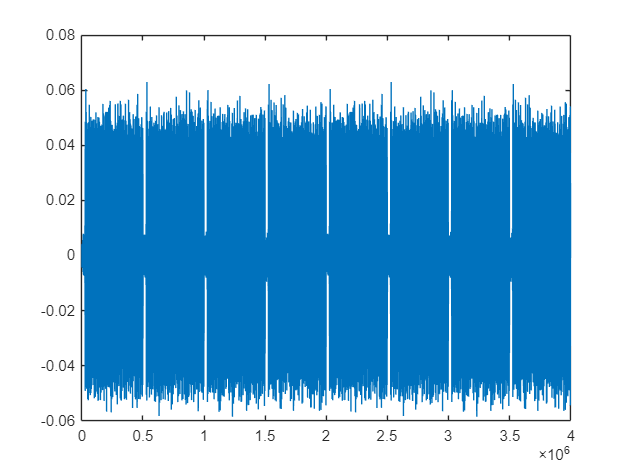

plot(real(rxWaveform));

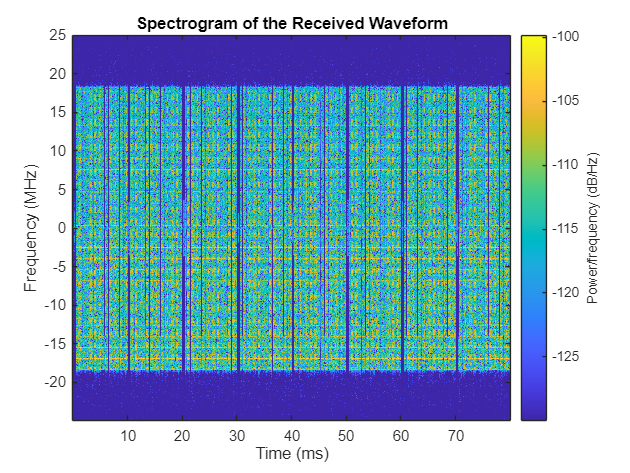

figure;
nfft = rxOfdmInfo.Nfft;
spectrogram(rxWaveform(:,1),ones(nfft,1),0,nfft,'centered',sampleRate,'yaxis','MinThreshold',-130);
title('Spectrogram of the Received Waveform')

## Frequency and Timining Offset Corrections and Primary Sync Signal (PSS) Block Search andProcessing

Correlate the frequency-shifted received waveform with each of the three possible PSS sequences (NID2) and extract the strongest correlation peak. The reference PSS sequences are centered in frequency. Therefore, the strongest correlation peak provides a measure of coarse frequency offset with respect to the center frequency of the carrier. The peak also indicates which of the three PSS (NID2) has been detected in the received waveform and the time instant of the best channel conditions.

disp(' -- Frequency correction and timing estimation --')

 -- Frequency correction and timing estimation --


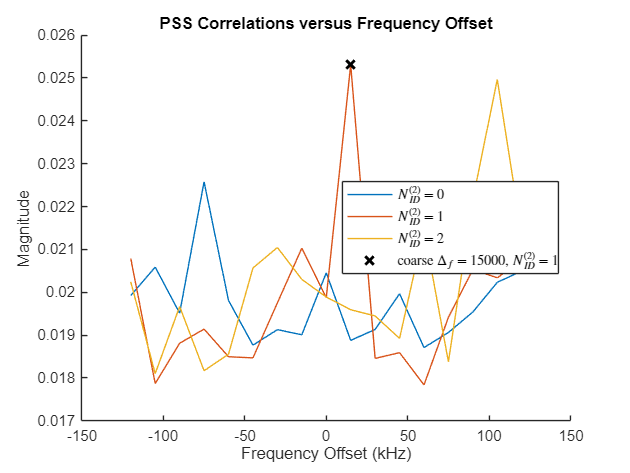

% Specify the frequency offset search bandwidth in kHz
searchBW = 8*scsSSB;  %Seacrh Space for timing offset
[rxWave,freqOffset,NID2] = hSSBurstFrequencyCorrect(rxWaveform,refBurst.BlockPattern,sampleRate,searchBW);  % FO Compensation

disp([' Frequency offset: ' num2str(freqOffset,'%.0f') ' Hz'])

 Frequency offset: 13077 Hz


% Create a reference grid for timing estimation using detected PSS. The PSS
% is placed in the second OFDM symbol of the reference grid to avoid the
% special CP length of the first OFDM symbol.
refGrid = zeros([nrbSSB*12 2]);
refGrid(nrPSSIndices,2) = nrPSS(NID2); % Second OFDM symbol for correct CP length

% Timing estimation. This is the timing offset to the OFDM symbol prior to
% the detected SSB due to the content of the reference grid
nSlot = 0;
timingOffset = nrTimingEstimate(rxWave,nrbSSB,scsSSB,nSlot,refGrid,'SampleRate',sampleRate);

% Synchronization, OFDM demodulation, and extraction of strongest SS block
rxGrid = nrOFDMDemodulate(rxWave(1+timingOffset:end,:),nrbSSB,scsSSB,nSlot,'SampleRate',sampleRate);
rxGrid = rxGrid(:,2:5,:);

% Display the timing offset in samples. As the symbol lengths are measured
% in FFT samples, scale the symbol lengths to account for the receiver
% sample rate.
srRatio = sampleRate/(scsSSB*1e3*rxOfdmInfo.Nfft);
firstSymbolLength = rxOfdmInfo.SymbolLengths(1)*srRatio;
str = sprintf(' Time offset to synchronization block: %%.0f samples (%%.%.0ff ms) \n',floor(log10(sampleRate))-3);
fprintf(str,timingOffset+firstSymbolLength,(timingOffset+firstSymbolLength)/sampleRate*1e3);

 Time offset to synchronization block: 3007187 samples (60.1437 ms) 


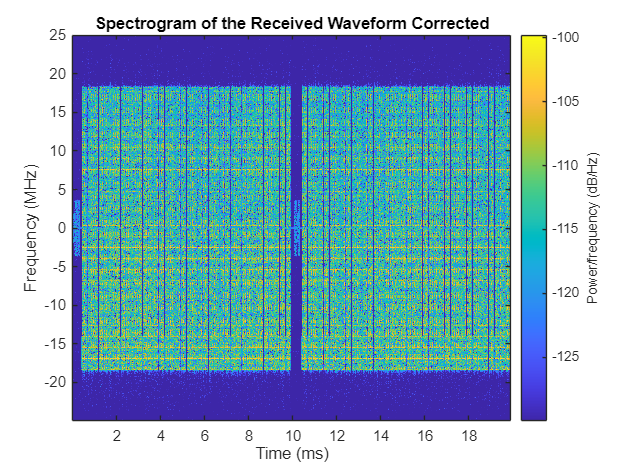

figure;
nfft = rxOfdmInfo.Nfft;
spectrogram(rxWaveform(1+timingOffset:end,1),ones(nfft,1),0,nfft,'centered',sampleRate,'yaxis','MinThreshold',-130);
title('Spectrogram of the Received Waveform Corrected')

## Secondary Sync Signal Block Search and Processing

The receiver extracts the resource elements associated to the SSS from the received grid and correlates them with each possible SSS sequence generated locally. The indices of the strongest PSS and SSS sequences combined give the physical layer cell identity, which is required for PBCH DM-RS and PBCH processing.

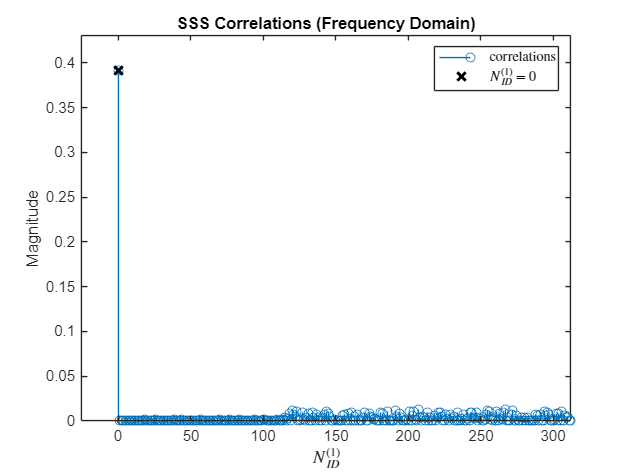

% Extract the received SSS symbols from the SS/PBCH block
sssIndices = nrSSSIndices;
sssRx = nrExtractResources(sssIndices,rxGrid);

% Correlate received SSS symbols with each possible SSS sequence
sssEst = zeros(1,336);
for NID1 = 0:335

    ncellid = (3*NID1) + NID2;
    sssRef = nrSSS(ncellid);
    sssEst(NID1+1) = sum(abs(mean(sssRx .* conj(sssRef),1)).^2);

end

% Plot SSS correlations
figure;
stem(0:335,sssEst,'o');
title('SSS Correlations (Frequency Domain)');
xlabel('$N_{ID}^{(1)}$','Interpreter','latex');
ylabel('Magnitude');
axis([-1 336 0 max(sssEst)*1.1]);

% Determine NID1 by finding the strongest correlation
NID1 = find(sssEst==max(sssEst)) - 1;

% Plot selected NID1
hold on;
plot(NID1,max(sssEst),'kx','LineWidth',2,'MarkerSize',8);
legend(["correlations" "$N_{ID}^{(1)}$ = " + num2str(NID1)],'Interpreter','latex');

xlim([-25 312])


% Form overall cell identity from estimated NID1 and NID2
ncellid = (3*NID1) + NID2;

disp([' Cell identity: ' num2str(ncellid)])

 Cell identity: 1


## Primary Broadcast Channel Processing

the receiver constructs each possible PBCH DM-RS sequence and performs channel and noise estimation. The index of the PBCH DM-RS with the best SNR determines the LSBs of the SS/PBCH block index required for PBCH scrambling initialization.

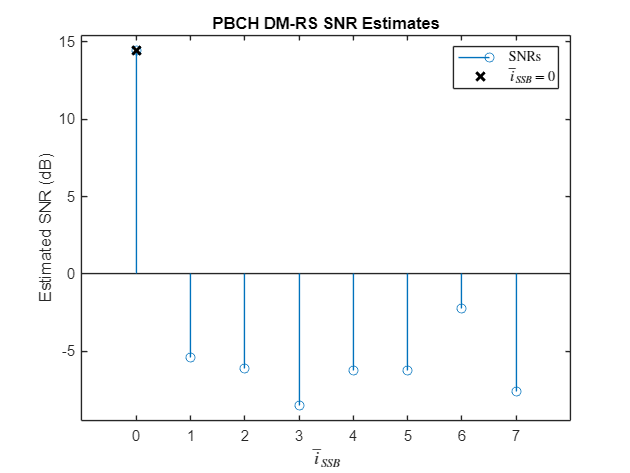

% Calculate PBCH DM-RS indices
dmrsIndices = nrPBCHDMRSIndices(ncellid);

% Perform channel estimation using DM-RS symbols for each possible DM-RS
% sequence and estimate the SNR
dmrsEst = zeros(1,8);
for ibar_SSB = 0:7

    refGrid = zeros([240 4]);
    refGrid(dmrsIndices) = nrPBCHDMRS(ncellid,ibar_SSB);
    [hest,nest] = nrChannelEstimate(rxGrid,refGrid,'AveragingWindow',[0 1]);
    dmrsEst(ibar_SSB+1) = 10*log10(mean(abs(hest(:).^2)) / nest);

end

% Plot PBCH DM-RS SNRs
figure;
stem(0:7,dmrsEst,'o');
title('PBCH DM-RS SNR Estimates');
xlabel('$\overline{i}_{SSB}$','Interpreter','latex');
xticks(0:7);
ylabel('Estimated SNR (dB)');
axis([-1 8 min(dmrsEst)-1 max(dmrsEst)+1]);

% Record ibar_SSB for the highest SNR
ibar_SSB = find(dmrsEst==max(dmrsEst)) - 1;

% Plot selected ibar_SSB
hold on;
plot(ibar_SSB,max(dmrsEst),'kx','LineWidth',2,'MarkerSize',8);
legend(["SNRs" "$\overline{i}_{SSB}$ = " + num2str(ibar_SSB)],'Interpreter','latex');

refGrid = zeros([nrbSSB*12 4]);
refGrid(dmrsIndices) = nrPBCHDMRS(ncellid,ibar_SSB);
refGrid(sssIndices) = nrSSS(ncellid);
[hest,nVar,hestInfo] = nrChannelEstimate(rxGrid,refGrid,'AveragingWindow',[0 1]);

## PBCH Demodulation

disp(' -- PBCH demodulation and BCH decoding -- ')

 -- PBCH demodulation and BCH decoding -- 


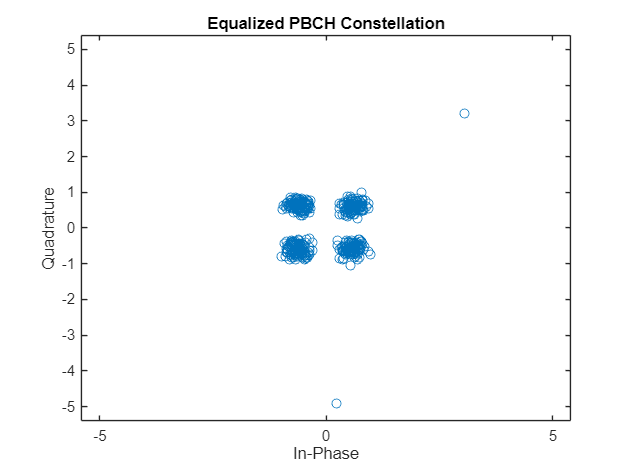


% Extract the received PBCH symbols from the SS/PBCH block
[pbchIndices,pbchIndicesInfo] = nrPBCHIndices(ncellid);
pbchRx = nrExtractResources(pbchIndices,rxGrid);

% Configure 'v' for PBCH scrambling according to TS 38.211 Section 7.3.3.1
% 'v' is also the 2 LSBs of the SS/PBCH block index for L_max=4, or the 3
% LSBs for L_max=8 or 64.
if refBurst.L_max == 4
    v = mod(ibar_SSB,4);
else
    v = ibar_SSB;
end
ssbIndex = v;

% PBCH equalization and CSI calculation
pbchHest = nrExtractResources(pbchIndices,hest);
[pbchEq,csi] = nrEqualizeMMSE(pbchRx,pbchHest,nVar);
Qm = pbchIndicesInfo.G / pbchIndicesInfo.Gd;
csi = repmat(csi.',Qm,1);
csi = reshape(csi,[],1);

% Plot received PBCH constellation after equalization
figure;
plot(pbchEq,'o');
xlabel('In-Phase'); ylabel('Quadrature')
title('Equalized PBCH Constellation');
m = max(abs([real(pbchEq(:)); imag(pbchEq(:))])) * 1.1;
axis([-m m -m m]);

% xlim([-1.51 1.32])
% ylim([-1.40 1.42])
% PBCH demodulation
pbchBits = nrPBCHDecode(pbchEq,ncellid,v,nVar);

% Calculate RMS PBCH EVM
pbchRef = nrPBCH(pbchBits<0,ncellid,v);
evm = comm.EVM;
pbchEVMrms = evm(pbchRef,pbchEq);

% Display calculated EVM
disp([' PBCH RMS EVM: ' num2str(pbchEVMrms,'%0.3f') '%']);

 PBCH RMS EVM: 35.833%


## BCH Decoding

% Apply CSI
pbchBits = pbchBits .* csi;

% Perform BCH decoding including rate recovery, polar decoding, and CRC
% decoding. PBCH descrambling and separation of the BCH transport block
% bits 'trblk' from 8 additional payload bits A...A+7 is also performed:
%   A ... A+3: 4 LSBs of system frame number
%         A+4: half frame number
% A+5 ... A+7: for L_max=64, 3 MSBs of the SS/PBCH block index
%              for L_max=4 or 8, A+5 is the MSB of subcarrier offset k_SSB
polarListLength = 8;
[~,crcBCH,trblk,sfn4lsb,nHalfFrame,msbidxoffset] = ...
    nrBCHDecode(pbchBits,polarListLength,refBurst.L_max,ncellid);

% Display the BCH CRC
disp([' BCH CRC: ' num2str(crcBCH)]);

 BCH CRC: 0



% Stop processing MIB and SIB1 if BCH was received with errors
if crcBCH
    disp(' BCH CRC is not zero.');
    return
end

% Use 'msbidxoffset' value to set bits of 'k_SSB' or 'ssbIndex', depending
% on the number of SS/PBCH blocks in the burst
if (refBurst.L_max==64)
    ssbIndex = ssbIndex + (bit2int(msbidxoffset,3) * 8);
    k_SSB = 0;
else
    k_SSB = msbidxoffset * 16;
end

% Displaying the SSB index
disp([' SSB index: ' num2str(ssbIndex)])

 SSB index: 0


## MIB and BCH Parsing

 Parses the 24 decoded BCH transport block bits into a MIB message and creates the `initialSystemInfo` structure with initial system information. 

% Parse the last 23 decoded BCH transport block bits into a MIB message.
% The BCH transport block 'trblk' is the RRC message BCCH-BCH-Message,
% consisting of a leading 0 bit and 23 bits corresponding to the MIB. The
% leading bit signals the message type transmitted (MIB or empty sequence).

mib = fromBits(MIB,trblk(2:end)); % Do not parse leading bit

% Create a structure containing complete initial system information
initialSystemInfo = initSystemInfo(mib,sfn4lsb,k_SSB,refBurst.L_max);

% Display the MIB structure
disp(' BCH/MIB Content:')

 BCH/MIB Content:


% Expected Output according to Config
%                      NFrame: 0
%     SubcarrierSpacingCommon: 30
%                       k_SSB: 12
%           DMRSTypeAPosition: 2
%             PDCCHConfigSIB1: [1×1 struct]
%                  CellBarred: 0
%        IntraFreqReselection: 0
disp(initialSystemInfo);

                     NFrame: 0
    SubcarrierSpacingCommon: 30
                      k_SSB: 0
          DMRSTypeAPosition: 2
            PDCCHConfigSIB1: [1×1 struct]
                 CellBarred: 0
       IntraFreqReselection: 0



## Local Funcs

function initSystemInfo = initSystemInfo(mib,sfn4lsb,k_SSB,L_max)

    % Create set of subcarrier spacings signaled by the 7th bit of the
    % decoded MIB, the set is different for FR1 (L_max=4 or 8) and FR2
    % (L_max=64)
    if (L_max==64)
        scsCommon = [60 120];
    else
        scsCommon = [15 30];
    end

    initSystemInfo = struct();
    initSystemInfo.NFrame = mib.systemFrameNumber*2^4 + bit2int(sfn4lsb,4);
    initSystemInfo.SubcarrierSpacingCommon = scsCommon(mib.subCarrierSpacingCommon + 1);
    initSystemInfo.k_SSB = k_SSB + mib.ssb_SubcarrierOffset;
    initSystemInfo.DMRSTypeAPosition = 2 + mib.dmrs_TypeA_Position;
    initSystemInfo.PDCCHConfigSIB1 = info(mib.pdcch_ConfigSIB1);
    initSystemInfo.CellBarred = mib.cellBarred;
    initSystemInfo.IntraFreqReselection = mib.intraFreqReselection;

end